clear
% Problem 1 

% Part (1)
% Z transform of difference equation 
syms y(n) z Ro
assume(n>=0 & in(n,"integer"))
virulence = 1.02; % Ro
f = y(n) - Ro*y(n-1) - kroneckerDelta(n);
fZT = ztrans(f,n,z);
syms yZT
fZT = subs(fZT,ztrans(y(n),n,z),yZT);
yZT = solve(fZT,yZT); 
yZT1 = subs(yZT,y(-1),0) % Transfer function H(z) = 1 / 1 - Ro*z^-1

$$yZT1 = -\frac{z}{\mathrm{Ro}-z}$$

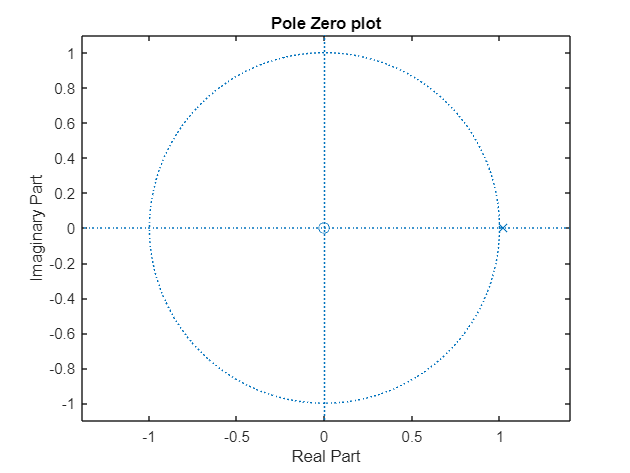

yZT = subs(yZT1,Ro,virulence); % Change Ro

[b,a] = numden(yZT);
num = sym2poly(b);
den = sym2poly(a);
zplane(num,den) % Pole Zero plot
title("Pole Zero plot")


% Part (2)
% Time domain Equation  
ySol = iztrans(yZT1,z,n); 
ySol = simplify(ySol) % Time domain equation y[n] = Ro^n u[n]

$$ySol = \left\{ \begin{array}{cl} \delta_{n,0} & \text{ if }\mathrm{Ro}=0\\ {\mathrm{Ro}}^{n} & \text{ if }\mathrm{Ro}\neq 0 \end{array}\right.$$

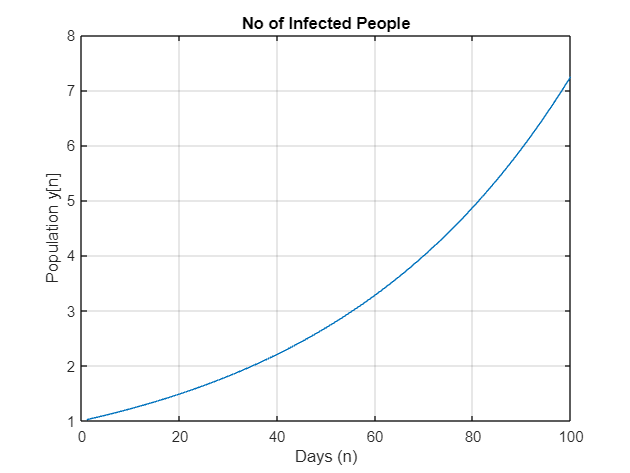

ySol = subs(ySol,Ro,virulence);
nValues = 1:100;
ySolValues = subs(ySol,n,nValues);
ySolValues = double(ySolValues);
ySolValues = real(ySolValues);
figure;
plot(nValues,ySolValues)
title("No of Infected People")
xlabel("Days (n)")
ylabel("Population y[n]")
grid on


% Part (3)
% Days for 1 million infections
% y[n] = 10^6
% Ro = 2.5
% n = log(y[n]) / log(Ro) (Days) 
Days =floor(6/log10(2.5))

Days = 15


% Part (4)
% Covid first wave March - November 2020 (250 Days)
% Ro is estimated at an interval of 50 days in this period  
population = [5 18885 285979 1637079 5213755 8951323];
Ro = [0];
for i = population
    Ro(population == i) = 10^(log10(i)/50);
end
Ro_phase1 = mean(Ro) % Ro during first wave 

Ro_phase1 = 1.2679


% Part (5)
days = 0:20;
Ro = 2.5;
populationx = [0];
for i = days
    populationx(days == i) = Ro^i;
end
% Integrator filter
% H(z) = 1 / 1-z^-1
Integrator = filter(1,[1 -1],populationx);
Total_infections = Integrator(end) % Total infections in 20 days

Total_infections = 1.5158e+08

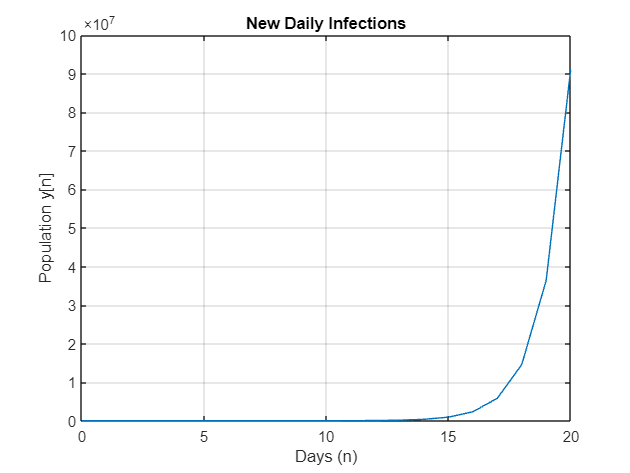


figure;
plot(days,populationx)
title("New Daily Infections")
xlabel("Days (n)")
ylabel("Population y[n]")
grid on